# 基于costmap全局路径规划

2024.2.18 初步完成路径规划任务，支持C/C++代码生成。

2024.2.21 完成以C++输出的costmap地图的全局路径规划任务。

## 预览costmap和里程计数据输出

本节为我写的C++代码输出costmap地图和里程计数据，测试路径规划使用。

### 文件说明

- odometeryIMUSimout.txt为C++输出的[$x$,$y$,$\theta$]一系列里程计数据，其中$x$,$y$单位为米，$\theta$单位为弧度。

- costMapFile.json为C++输出的costMap文件，保存为json格式，方便阅读和调试。

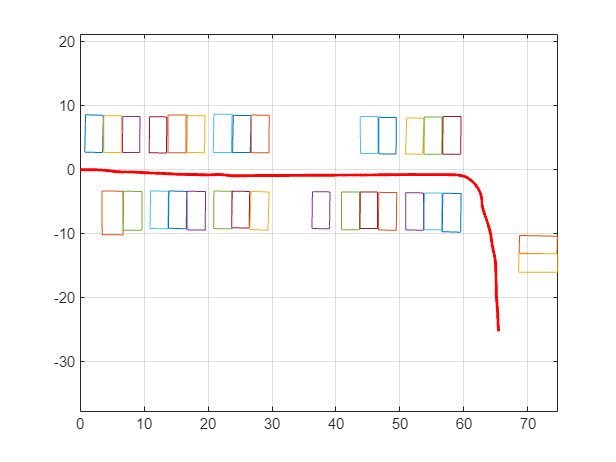

odometry = readmatrix("data/odometeryIMUSimout.txt");
odometry(end,:) = [];
txt = fileread("data/costMapFile.json");
st = jsondecode(txt);
x1 = [st.m_parkSpace.x1];
y1 = [st.m_parkSpace.y1];
x2 = [st.m_parkSpace.x2];
y2 = [st.m_parkSpace.y2];
x3 = [st.m_parkSpace.x3];
y3 = [st.m_parkSpace.y3];
x4 = [st.m_parkSpace.x4];
y4 = [st.m_parkSpace.y4];
plot([x1;x2;x3;x4;x1],[y1;y2;y3;y4;y1]);
grid on;
axis equal;
hold on;
plot(odometry(:,1),odometry(:,2),'r-',LineWidth=2)

### 构建costmap地图

由C++产生的像素地图，构建costmap地图。注意：每个像素就代表一个occupancy网格grid cell。C++中的分辨率m_resolution单位为：米/pixel，而以下内置的occupancyMap函数单位为grid cells/米，正好互为倒数。 result.png为C++输出的像素costmap地图。

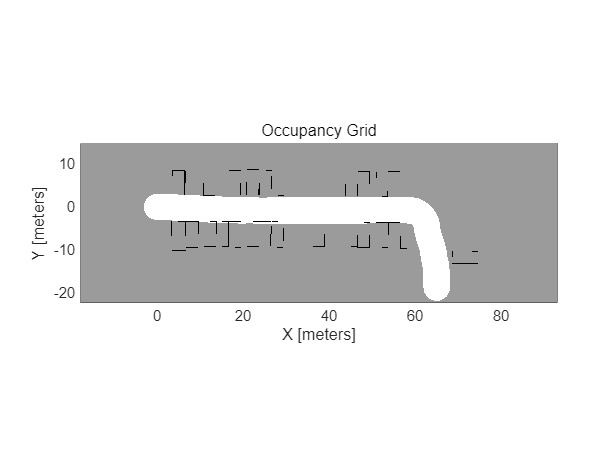

costmapImg = im2single(imread("data/result.png"));
res = 1/st.m_resolution;
map = occupancyMap(costmapImg,res);
map.LocalOriginInWorld = [st.m_worldXRange.value0,st.m_worldYRange.value0];
map.show()

## 路径规划

以下为单独的路径规划算法，使用混合A*。给定像素地图mapData，起始姿态startPose，终止姿态goalPose，可以规划出一系列的航点坐标path。

mapData = occupancyMatrix(map);
startPose = [0,0,0];
goalPose = [65,-17,-pi/2];

path = pathPlan(mapData,startPose,goalPose,res,map.LocalOriginInWorld);

可视化规划轨迹

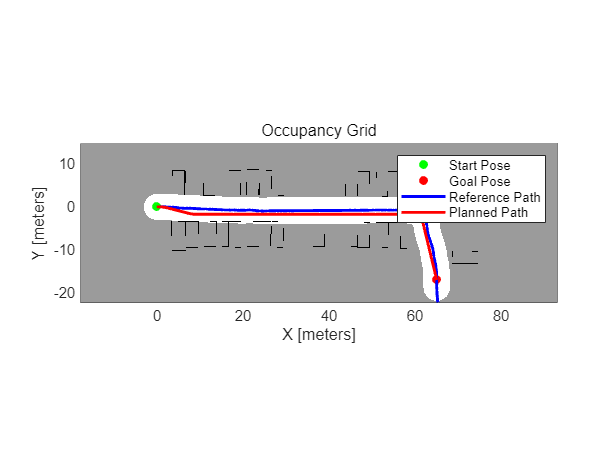

show(map)
hold on
% Start state
obj1 = scatter(startPose(1,1),startPose(1,2),"g","filled");
% Goal state
obj2 = scatter(goalPose(1,1),goalPose(1,2),"r","filled");
% ground truth
obj3 = plot(odometry(:,1),odometry(:,2),'b-',LineWidth=2);
% Path
obj4 = plot(path(:,1),path(:,2),"r-",LineWidth=2);
legend([obj1,obj2,obj3,obj4],["Start Pose","Goal Pose","Reference Path","Planned Path"]);
hold off;

## 生成C/C++测试

mexPath = pathPlan_mex(mapData,startPose,goalPose,res,map.LocalOriginInWorld);

函数或变量 'pathPlan_mex' 无法识别。

可视化规划轨迹

figure;show(map)
hold on
% Start state
obj1 = scatter(startPose(1,1),startPose(1,2),"g","filled");
% Goal state
obj2 = scatter(goalPose(1,1),goalPose(1,2),"r","filled");
% planned truth
obj3 = plot(path(:,1),path(:,2),'b-',LineWidth=2);
% mex 
obj4 = plot(path(:,1),path(:,2),'k--',LineWidth=2);
legend([obj1,obj2,obj3,obj4],["Start Pose","Goal Pose","Planned Path","Mex Planned Path"]);
hold off;

time = timeit(@() pathPlan(mapData,startPose,goalPose,res,map.LocalOriginInWorld))

mexTime = timeit(@() pathPlan_mex(mapData,startPose,goalPose,res,map.LocalOriginInWorld))

time/mexTime